# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验六 模拟原型滤波器及IIR数字滤波器

## 一、实验目的

- 掌握模拟低通滤波器原型的设计方法

- 掌握模拟低通滤波器原型进行频率变换的方法

- 学习MATLAB模拟原型滤波器设计子函数的使用方法

- 掌握模拟滤波器原型进行脉冲响应变换的方法

- 掌握用双线性变换法设计IIR数字滤波器的方法

- 学习MATLAB直接设计IIR模拟滤波器和数字滤波器的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

        1.模拟滤波器基本知识

            输入信号和输出信号均为连续时间信号，冲激响应也是连续的滤波器称为模拟滤波器。模拟滤波器从功能上可以分为低通、高通、带通、带阻以及全通滤波器。理想的幅度频率特性曲线如图所示。

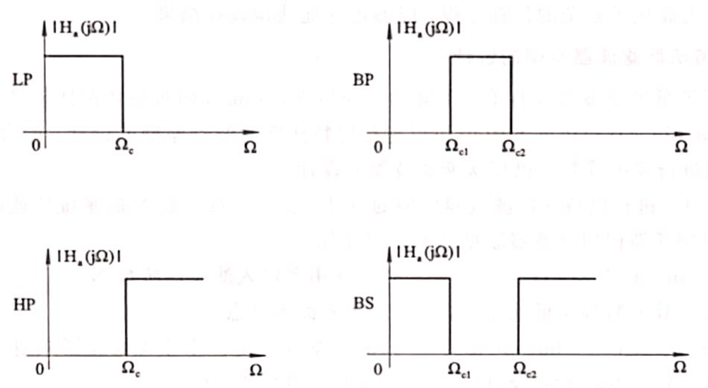

            实际使用中理想滤波器是不可实现的，必须设计一个因果可实现的滤波器去逼近。通常，通带和阻带都允许存在一定的误差容限，即通带不一定是完全水平的，阻带也不一定绝对衰减到0。在通带和阻带之间允许设置一定宽度的过渡带。

            归一化低通滤波器的幅频特性曲线如图所示。

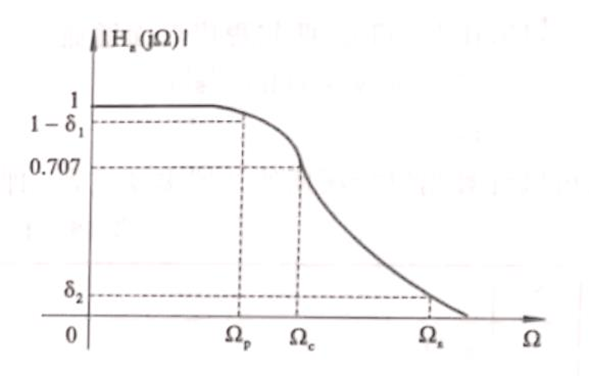

            图中，$\Omega_p$为通带截止频率，$\Omega_c$为3 dB通带截止频率,$\Omega_s$为阻带截止频率。在$0\le \Omega \le \Omega_p$的通带范围内，幅度要求在${\left(1-\delta_1 \right)}<\left|H_a {\left(j\Omega \right)}\left|\le 1\right.$范围内;在$\Omega \ge \Omega_s$的阻带范围内，幅度要求${\left|H_a {\left(j\Omega \right)}\right|}\le \delta_2$;从$\Omega_p$到$\Omega_s$的范围称为过渡带。通带和阻带内的允许衰减一般用dB数表示，通带内允许的最大衰减用$a_p$($\left.R_p \right)$表示，阻带内允许的最小衰减用$a_s$($\left.A_s \right)$或表示。通带与阻带的衰减$a_p$和$a_s$ 分别定义为:


$$a_p =10lg\frac{{\left|H_a \left(j0\right)\right|}^2 }{{\left|H_a \left(j\Omega_p \right)\right|}^2 }=-10lg{\left|H_a \left(j\Omega_p \right)\right|}^2$$



$$a_s =10lg\frac{{\left|H_a \left(j0\right)\right|}^2 }{{\left|H_a \left(j\Omega_s \right)\right|}^2 }=-10lg{\left|H_a \left(j\Omega_s \right)\right|}^2$$


            其中，$\left|H_a \left(j0\right)\right|$已被归一化为1。当$\left|H_a \left(j\Omega \right)\right|$下降为1/$\surd 2$=0. 707时，对应的$a_p =3dB$,即$\Omega =\Omega_c$。其它常用的数据有:当$a_p =1dB$时，${\left|H_a {\left(j\Omega \right)}\right|}=0.8913$；当${\left|H_a {\left(j\Omega \right)}\right|}=0.01$时，$a_s =40dB$。

            典型的模拟滤波器有巴特沃斯(Butterworth)滤波器、切比雪夫(Chebyshev)滤波器、椭圆Ellipse)滤波器、贝塞尔(Bessel)滤波器等。每种典型滤波器都有其不同的特点。由于IIR数字滤波器是在已知的低通模拟滤波器的基础上设计的，主要包括巴特沃斯低通滤波器、切比雪夫低通滤波器、椭圆低通滤波器，因此，我们把这些模拟低通滤波器称为滤波器原型。

            巴特沃斯低通滤波器具有单调下降的幅频特性，通带和阻带幅频都比较平坦。

            切比雪夫（Ⅰ型）滤波器在通带内具有等波动的幅频响应。

            切比雪夫（Ⅱ型）滤波器在阻带内具有等波动的幅频响应。

        2.模拟域频率变换法

            IIR数字滤波器的设计，通常采用模拟域频率变换法和数字域频率变换法来实现。模拟域频率变换法的基本设计思想是:先进行频率变换，后进行数字化变换。即在模拟低通滤波器原型设计好以后，通过频率变换，将模拟低通滤波器原型变换成实际的模拟低通、高通、带通、带阻滤波器。再通过相应的变换方法，将模拟滤波器变换成数字滤波器。

        3.脉冲响应不变法设计数字滤波器

            脉冲响应不变法又称为冲激响应不变法，是将系统从s平面到z平面的一种映射方法，使数字滤波器的单位脉冲响应序列h(n)模仿模拟滤波器的冲激响应h(n).其变换关系式为z=$e^{sT}$。

            由于$e^{sT}$是一个周期函数，因而s平面虚轴上每一段2π/T的线段都映射到z平面单位圆上一周。由于重叠映射，因而冲激响应不变法是一种多值映射关系。数字滤波器的频率响应是原模拟滤波器的频率响应的周期延拓。只有当模拟滤波器的频率响应是有限带宽的，且频带宽度${\left|\Omega \right|}\le \frac{\pi }{T}=\frac{\Omega_s }{2}$，才能避免数字滤波器的频率响应发生混叠的现象。由于脉冲响应不变法只适用于限带的模拟滤波器，因此，在高频区幅频特性不等于零的高通和带阻滤波器不能采用脉冲响应不变法。

            用MATLAB冲激响应不变法进行IIR数字滤波器设计的步骤如下:

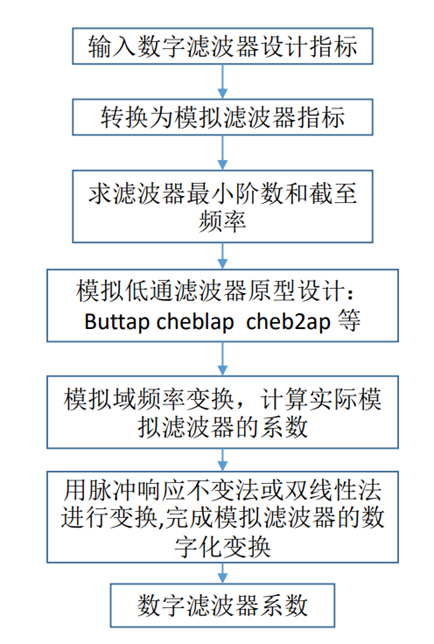

        4.双线性变换法设计数字滤波器

            双线性变换法是将整个s平面映射到整个z平面，其映射关系为$s=\frac{2}{T}\frac{1-z^{-1} }{1+z^{-1} }$或$z=\frac{1+sT/2}{1-sT/2}$。双线性变换法克服了脉冲响应不变法从s平面到z平面的多值映射的缺点，消除了频谱混叠现象。但其在变换过程中产生了非线性的畸变，在设计IIR数字滤波器的过程中需要进行一定的预修正。

        5.用直接法设计模拟和数字滤波器

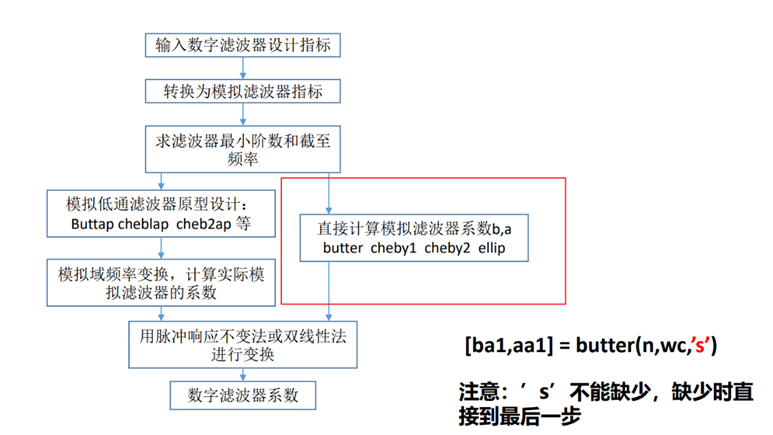

## 四、实验所用MATLAB函数

- buttord函数：确定巴特沃斯(Butterworth)滤波器的阶数和3 dB截止频率。

- cheb1ord函数：确定切比雪夫(Chebyshev)I型滤波器的阶数和通带截止频率。

- cheb2ord函数：确定切比雪夫(Chebyshev)II型滤波器的阶数和阻带截止频率。

- ellipord函数：确定椭圆(Ellipse)滤波器的阶数和通带截止频率。

- buttap函数：巴特沃斯(Butterworth)模拟低通滤波器原型。

- cheb1ap函数：切比雪夫(Chebyshev)I型模拟低通滤波器原型。

- cheb2ap函数：切比雪夫(Chebyshev) II型模拟低通滤波器原型。

- poly函数：求某向量指定根所对应的特征多项式。

- poly2tr函数：以习惯方式显示多项式。

- pzmap函数：显示连续系统的零极点分布图。

- Ip2lp函数：低通到低通模拟滤波器变换。这种变换是使用butter、cheby1、cheby2数设计数字低通滤波器的一个步骤。

- Ip2hp函数：低通到高通模拟滤波器变换。这种变换是使用butter、cheby1、cheby2函数设计数字高通滤波器的一个步骤。

- lp2bp函数：低通到带通模拟滤波器变换。这种变换是使用butter.cheby1、cheby2函数设计数字带通滤波器的一个步骤。

- lp2bs函数：低通到带阻模拟滤波器变换。这种变换是使用butter. cheby1、cheby2函数设计数字带阻滤波器的一个步骤。

-  impinvar函数：用脉冲响应不变法实现模拟到数字的滤波器变换。

- bilinear函数：双线性变换将 s域(模拟域)映射到z域(数字域)的标准方法，将模拟滤波器变换成离散等效滤波器。

- butter函数：巴特沃斯(Butterworth)模拟或数字滤波器设计。

- cheby1函数：切比雪夫I型滤波器设计(通带等波纹)。

- cheby2函数：切比雪夫Ⅱ型滤波器设计(通带等波纹)。

## 五、实验内容、方法、代码与结果

### **题目1**：设计一个*模拟原型低通滤波器*，通带截止频率$f_p=6kHz$，通带最大衰减$R_p\le1dB$，阻带截止频率$f_s=15kHz$，阻带最小衰减$A_s\ge30dB$。要求：实现符合以上指标的巴特沃斯滤波器，绘制幅频特性和相频特性曲线、零极点分布图，并列写出传递函数表达式。

**解答1**：

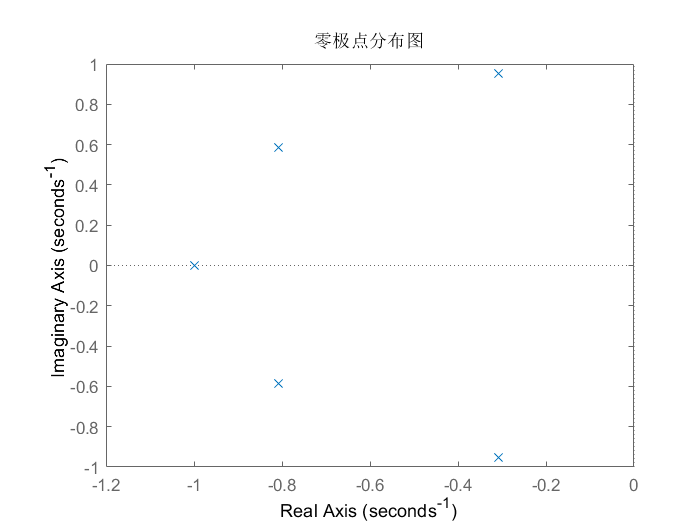

clc;
clear;
fp=6e3;
wp=2*pi*fp;
Rp=1;
fs=15e3;
ws=2*pi*fs;
As=30;
[n,wc]=buttord(wp,ws,Rp,As,'s');
[z,p,k]=buttap(n);
b=k*real(poly(z));
a=real(poly(p));

figure();
pzmap(b,a);
title('零极点分布图');

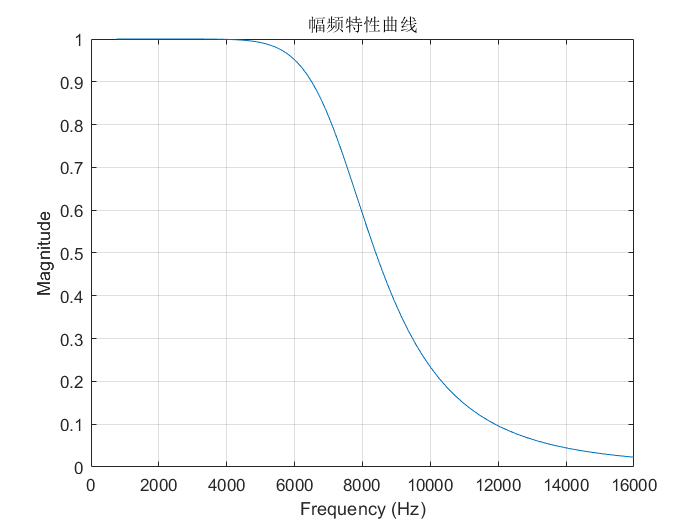

[h,w]=freqs(b,a);

figure();
plot(w*wc/(2*pi),abs(h));
grid on
xlabel('Frequency (Hz)')
ylabel('Magnitude');
axis([0,16e3,0,1]);
title('幅频特性曲线');

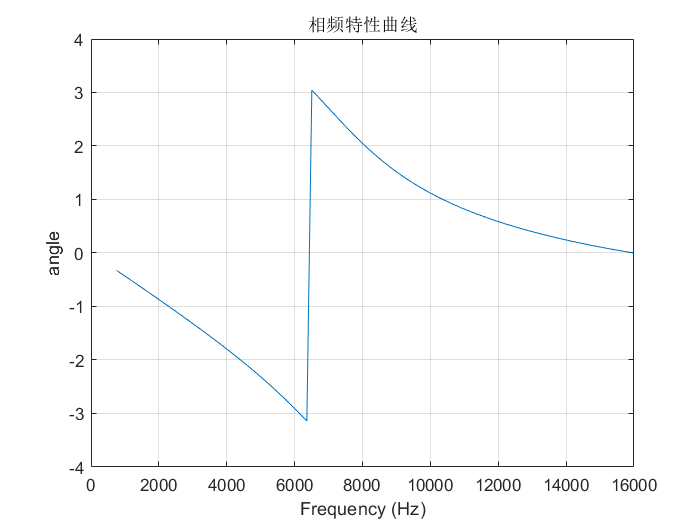


figure();
plot(w*wc/(2*pi),angle(h));
grid on
xlabel('Frequency (Hz)');
ylabel('angle');
axis([0,16e3,-4,4]);
title('相频特性曲线');


syms s 
sum=0;
for i =0:n
   sum=a(i+1)*(s/wc)^i+sum; 
end
hs=1/sum;
disp(vpa(hs));

$$\frac{1}{0.0000000000000000000000042503736159717479440567889000136\,s^{5}+0.00000000000000000064976949958739381357190068866792\,s^{4}+0.000000000000049666269455411863066804631582666\,s^{3}+0.0000000023462599045963433985656254926788\,s^{2}+0.000068501969381855632332913690909999\,s+1.0}$$

### **题目2**：用*频率变换法*设计一个*切比雪夫Ⅱ型模拟低通滤波器*，要求通带截止频率$f_p=3.5kHz$，通带最大衰减$R_p\le1dB$，阻带截止频率$f_s=6kHz$，阻带最小衰减$A_s\ge40dB$。绘制归一化的模拟滤波器原型和实际模拟低通滤波器的频率特性。

**解答2**：

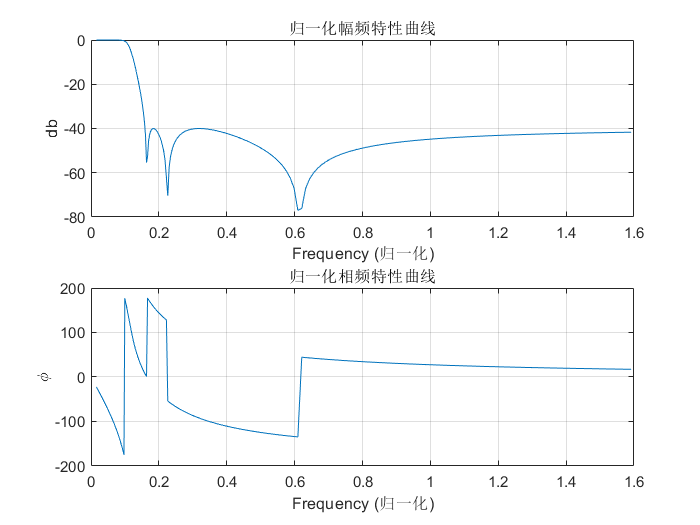

clc;
clear;
fp=3.5e3;
wp=2*pi*fp;
Rp=1;
fs=6e3;
ws=2*pi*fs;
As=40;
[n,wc]=cheb2ord(wp,ws,Rp,As,'s');
[z,p,k]=cheb2ap(n,As);
b=k*real(poly(z));
a=real(poly(p));
[h,w]=freqs(b,a);
[ba,aa]=lp2lp(b,a,wc);
[ha,wa]=freqs(ba,aa);

figure();
subplot(2,1,1);
dbh=20*log10(abs(h)/max(abs(h)));
plot(w/(2*pi),dbh);
grid on
xlabel('Frequency (归一化)')
ylabel('db');
title('归一化幅频特性曲线');
 
subplot(2,1,2);
plot(w/(2*pi),angle(h)/pi*180);
grid on
xlabel('Frequency (归一化)');
ylabel('\phi')
title('归一化相频特性曲线');

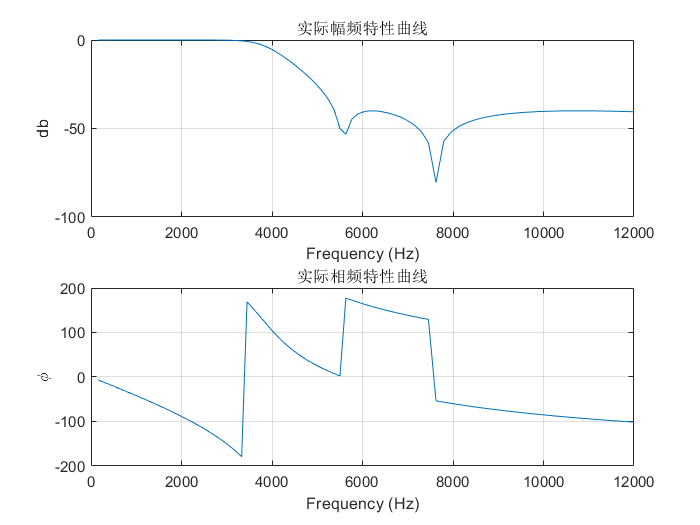


figure();
subplot(2,1,1);
dbha=20*log10(abs(ha)/max(abs(ha)));
plot(wa/(2*pi),dbha);
grid on
xlabel('Frequency (Hz)')
ylabel('db');
title('实际幅频特性曲线');
xlim([0,2*fs]);

subplot(2,1,2);
plot(wa/(2*pi),angle(ha)/pi*180);
grid on
xlabel('Frequency (Hz)');
ylabel('\phi')
title('实际相频特性曲线');
xlim([0,2*fs]);

### **题目3**：采用*双线性变换法*设计一个*切比雪夫Ⅱ型数字带通滤波器*，要求通带$f_{p1}=200Hz,f_{p2}=300Hz,R_p=1dB$；阻带$f_{s1}=150Hz,f_{s2}=350Hz,A_s=20dB$，滤波器采样频率$F_s=1000Hz$。列出传递函数并作频率响应曲线和零极点分布图。

**解答3**：

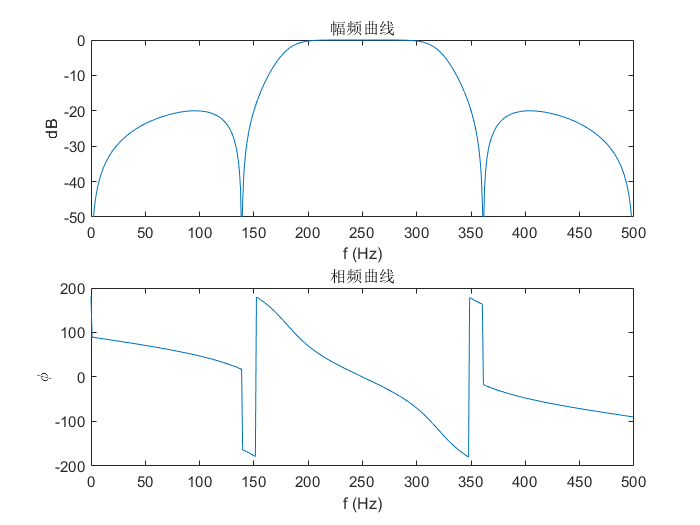

clc;
clear;
Fs=1000;
T=1/Fs;
fp1=200*T;fp2=300*T;
Rp=1;
fs1=150*T;
fs2=350*T;
As=20;
wp1=2*pi*fp1;wp2=2*pi*fp2;ws1=2*pi*fs1;ws2=2*pi*fs2;
wp=[wp1,wp2];
ws=[ws1,ws2];
omgp=(2/T)*tan(wp/2);
omgs=(2/T)*tan(ws/2);
bw=omgs(2)-omgs(1);
w0=sqrt(omgs(2)*omgs(1));
[n,wc]=cheb2ord(omgp,omgs,Rp,As,'s');
[z,p,k]=cheb2ap(n,As);
b=k*real(poly(z));
a=real(poly(p));
[ba,aa]=lp2bp(b,a,w0,bw);
[bd,ad]=bilinear(ba,aa,Fs);
[hd,omgd]=freqz(bd,ad);
dbha=20*log10(abs(hd)/max(abs(hd)));
figure();
subplot(2,1,1);
plot(omgd/(2*pi)*Fs,dbha);
xlabel('f (Hz)');
ylabel('dB');
title('幅频曲线');
axis([0 500 -50 0]);
subplot(2,1,2);
plot(omgd/(2*pi)*Fs,angle(hd)/pi*180);
xlabel('f (Hz)');
ylabel('\phi');
title('相频曲线');

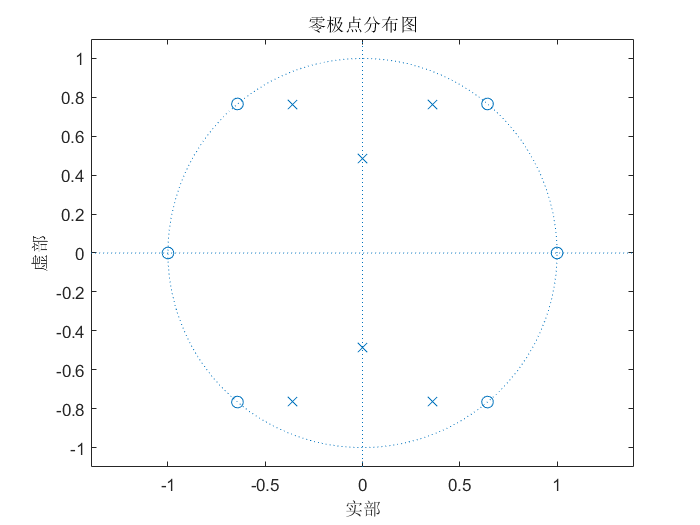


figure();
zplane(bd,ad);
title('零极点分布图');


syms z;
son=0;monther=0;
for indax=0:length(bd)-1
    son=son+bd(indax+1)*z^-indax;
end
for indax=0:length(ad)-1
    monther=monther+ad(indax+1)*z^-indax;
end
result=son/monther;
disp(vpa(result));

$$-\frac{1.0\,\left(\frac{0.0000000000000021208673540614181960933604219929}{z}+\frac{0.091102719747841010011768503318308}{z^{2}}-\frac{0.0000000000000024252349045419061760768200820952}{z^{3}}-\frac{0.091102719747839566721836490614805}{z^{4}}+\frac{0.00000000000000026936453078289364147737546710777}{z^{5}}+\frac{0.13965689583592180711413277549582}{z^{6}}-0.13965689583592233447006947244518\right)}{\frac{1.1454361912111525878543716316926}{z^{2}}-\frac{0.0000000000000032773263269891828031177283264697}{z}-\frac{0.0000000000000036254423146254160810338581702794}{z^{3}}+\frac{0.72745800269867488818675838047056}{z^{4}}-\frac{0.0000000000000015580514894996380241136245705752}{z^{5}}+\frac{0.12050258031999784569254785537851}{z^{6}}+1.0}$$

### **题目4**：用*MATLAB直接法*设计*切比雪夫Ⅰ型数字带阻滤波器*，要求：$f_{p1}=1kHz,f_{p2}=4.5kHz,R_p=1dB$；阻带$f_{s1}=2kHz,f_{s2}=3.5kHz,A_s=20dB$，滤波器采样频率$F_s=10kHz$。请描绘滤波器绝对和相对幅频特性、相频特性、零极点分布图，列出系统传递函数式。

**解答4**：

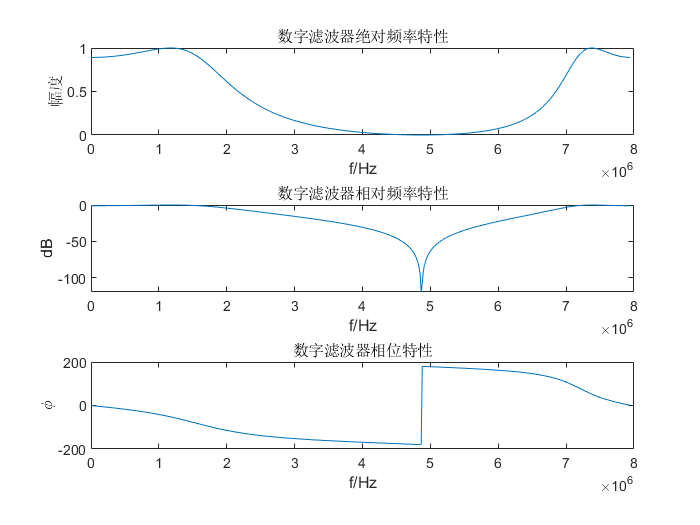

clc;
clear;
figure();
Fs=10000;
fs1=2000;ws1=2*pi*fs1/Fs;
fs2=3500;ws2=2*pi*fs2/Fs;0
ws=[ws1,ws2]/pi;
fp1=1000;wp1=2*pi*fp1/Fs;
fp2=4500;wp2=2*pi*fp2/Fs;
wp=[wp1,wp2]/pi;
Rp=1;As=20;
[n,wc]=cheb1ord(wp,ws,Rp,As);
[b,a]=cheby1(n,Rp,wc,'stop');
[HH,w]=freqz(b,a,512,Fs);
dbH=20*log10(abs(HH)/max(abs(HH)));
subplot(3,1,1);
plot(w/(2*pi)*Fs,abs(HH));
xlabel('f/Hz');
ylabel('幅度');
title('数字滤波器绝对频率特性');
subplot(3,1,2);
plot(w/(2*pi)*Fs,dbH);
xlabel('f/Hz');
ylabel('dB');
title('数字滤波器相对频率特性');
subplot(3,1,3);
plot(w/(2*pi)*Fs,angle(HH)/pi*180)
xlabel('f/Hz');
ylabel('\phi');
title('数字滤波器相位特性');

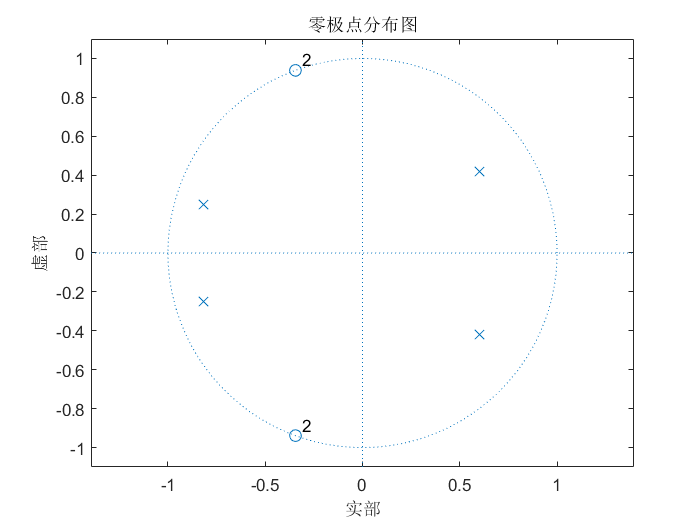


figure();
zplane(b,a);
title('零极点分布图');

syms z
son=0;monther=0;
for indax=0:length(b)-1
    son=son+b(indax+1)*z^-indax;
end
for indax=0:length(a)-1
    monther=monther+a(indax+1)*z^-indax;
end
result=son/monther;
disp(vpa(result));

$$\frac{\frac{0.19051691941040113653649257230427}{z}+\frac{0.34209847384831909566926810839504}{z^{2}}+\frac{0.19051691941040110878091695667536}{z^{3}}+\frac{0.13822540868747065778698868143692}{z^{4}}+0.13822540868747068554256429706584}{\frac{0.42262204689068016971731367448228}{z}-\frac{0.69984516781376715499618512694724}{z^{2}}+\frac{0.004904951979780247661722114571603}{z^{3}}+\frac{0.39386888746166437424989226201433}{z^{4}}+1.0}$$

### **题目5**`：`***采用脉冲响应不变法设计一个巴特沃兹数字带通滤波器******，*****要求：**

### 通带$w_{p1}=0.3\pi ,w_{p2}=0.7\pi ,R_p=1dB;$阻带$w_{s1}=0.1\pi ,w_{s2}=0.9\pi ,A_s=15dB;$滤波器采样频率$F_s=2000Hz$。试显示数字滤波器的幅频特性和零极点分布图，并写出该系统的传递函数。

**解答5**：

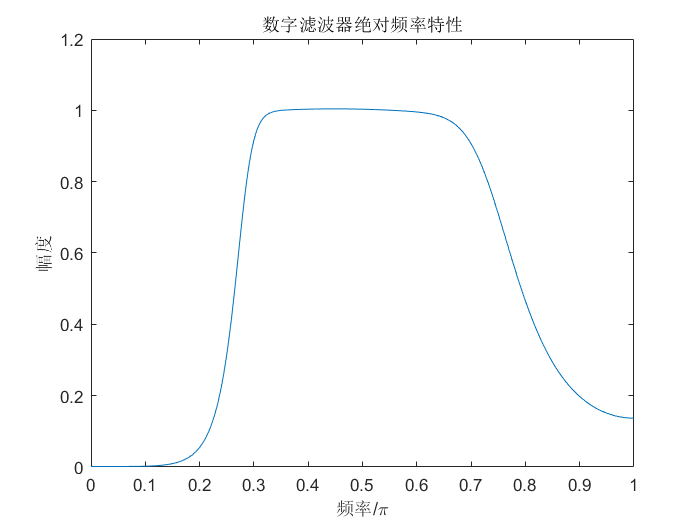

clc;
clear;
figure();
wp1=0.3*pi;wp2=0.7*pi;
ws1=0.1*pi;ws2=0.9*pi;
Rp=1;As=15;
Fs=2000;T=1/Fs;
Omgp1=wp1*Fs;
Omgp2=wp2*Fs;
Omgp=[Omgp1,Omgp2];
Omgs1=ws1*Fs;
Omgs2=ws2*Fs;
Omgs=[Omgs1,Omgs2];
bw=Omgp2-Omgp1;
w0=sqrt(Omgp1*Omgp2);
[n,Omgc]=buttord(Omgp,Omgs,Rp,As,'s');
[ba,aa]=butter(n,Omgc,'s');
[bd,ad]=impinvar(ba,aa,Fs);
[C,B,A]=dir2par(bd,ad);
[HH,w]=freqz(bd,ad,Fs);
dbH=20*log10(abs(HH)/max(abs(HH)));

figure();
plot(w/(pi),abs(HH));
xlabel('频率/\pi');
ylabel('幅度');
title('数字滤波器绝对频率特性');

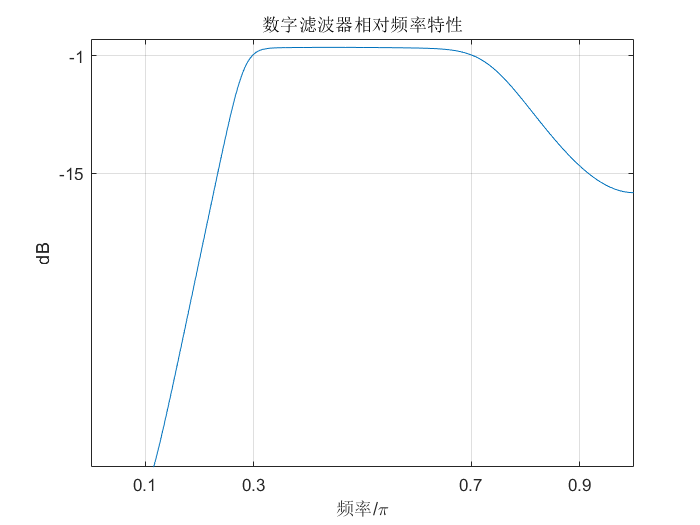


figure();
plot(w/(pi),dbH);
xlabel('频率/\pi');
ylabel('dB');
title('数字滤波器相对频率特性');
set(gca,'Xtick',[0.1,0.3,0.7,0.9]);
set(gca,'Ytick',[-15,-1]);grid
axis([0 1 -50 1]);

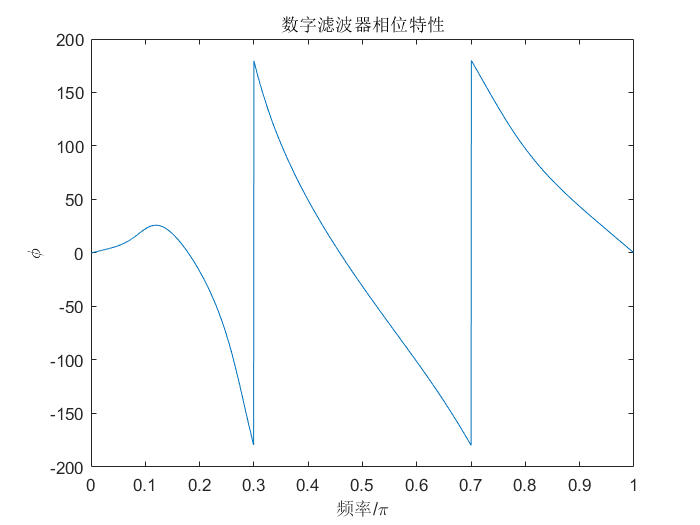


figure();
plot(w/(pi),angle(HH)/pi*180);
xlabel('频率/\pi');
ylabel('\phi');
title('数字滤波器相位特性');

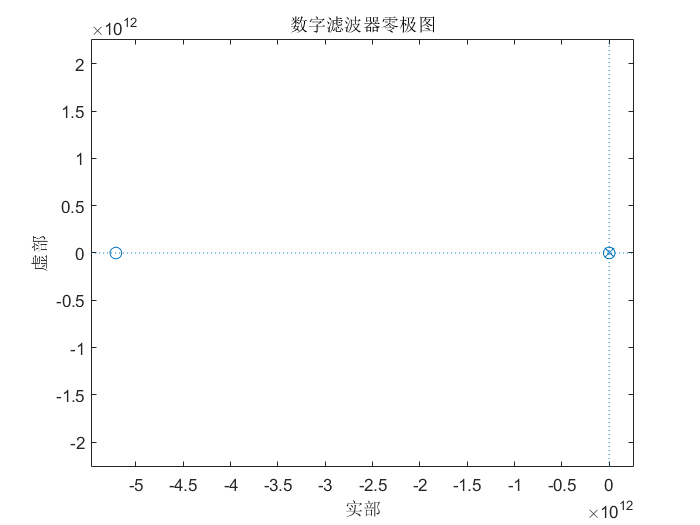


figure();
zplane(bd,ad);
title('数字滤波器零极图');

syms z
son=0;monther=0;
for indax=0:length(bd)-1
    son=son+bd(indax+1)*z^-indax;
end
for indax=0:length(ad)-1
    monther=monther+ad(indax+1)*z^-indax;
end
result=son/monther;
disp(vpa(result));

$$\frac{\frac{0.067781163671063168751906857778522}{z}-\frac{0.17469326464459289383057694067247}{z^{2}}-\frac{0.034234472020514598866736122317889}{z^{3}}+\frac{0.51498238401233131789069830119843}{z^{4}}-\frac{0.52509461341594443339886311150622}{z^{5}}+\frac{0.069634653568142024226972353062592}{z^{6}}+\frac{0.12991394370150685655396216588997}{z^{7}}-\frac{0.041887392107327094115110099892263}{z^{8}}-\frac{0.0043443060641376691696780021345603}{z^{9}}+0.000000000000013002932064409833906312553438127}{\frac{1.2226841632789202662934258114547}{z^{2}}-\frac{1.0114295304126883490170030199806}{z}-\frac{0.48941396189408936656661808228819}{z^{3}}+\frac{0.71795408549507033768577457522042}{z^{4}}-\frac{0.3452652633356142475307137829077}{z^{5}}+\frac{0.36486213743469897430315995734418}{z^{6}}-\frac{0.10650036663608852816054195500328}{z^{7}}+\frac{0.082812625909921971922855732373137}{z^{8}}-\frac{0.013021411282249118271381327360814}{z^{9}}+\frac{0.0081184186662738733880617658655865}{z^{10}}+1.0}$$

function [C,B,A] = dir2par(b,a);
% DIRECT-form to PARALLEL-form conversion
% --------------------------------------
% [C,B,A] = dir2par(b,a)
%  C = Polynomial part when length(b) >= length(a)
%  B = K by 2 matrix of real coefficients containing bk's
%  A = K by 3 matrix of real coefficients containing ak's
%  b = numerator polynomial coefficients of DIRECT form
%  a = denominator polynomial coefficients of DIRECT form
%

M = length(b); N = length(a);

[r1,p1,C] = residuez(b,a);
p = cplxpair(p1,10000000*eps);
I = cplxcomp(p1,p);
r = r1(I);

K = floor(N/2); B = zeros(K,2); A = zeros(K,3);
if K*2 == N; %N even, order of A(z) odd, one factor is first order
        for i=1:2:N-2
                Brow = r(i:1:i+1,:);
                Arow = p(i:1:i+1,:);
                [Brow,Arow] = residuez(Brow,Arow,[]);
                B(fix((i+1)/2),:) = real(Brow);
                A(fix((i+1)/2),:) = real(Arow);
        end
        [Brow,Arow] = residuez(r(N-1),p(N-1),[]);
        B(K,:) = [real(Brow) 0]; A(K,:) = [real(Arow) 0];
else
        for i=1:2:N-1
                Brow = r(i:1:i+1,:);
                Arow = p(i:1:i+1,:);
                [Brow,Arow] = residuez(Brow,Arow,[]);
                B(fix((i+1)/2),:) = real(Brow);
                A(fix((i+1)/2),:) = real(Arow);
        end
end
end

function I=cplxcomp(p1,p2)
I=[];
for j=1:1:length(p2)
for i=1:1:length(p1)
if (abs(p1(i)-p2(j))<0.0001)
I=[I,i];
end
end
end
I=I';
end